# Time Analysis Program

Author: M. Noyce 

Description: Extraction of full dataset from each buoy and plotting the key wave parameters.

For reference the depoyment and retrieval times (UTC) were:

**Buoy        Deployment                Retrieval**

SB01        2022-07-19 13:20        2022-07-24 12:25    

SB02        2022-07-19 18:00        N/A

SB03        2022-07-20 01:45        N/A

SB04        2022-07-20 15:40        2022-07-24 07:50  

SB05        2022-07-20 07:40        2022-07-24 14:00  

SB06        2022-07-20 19:10        2022-07-23 09:20

## Import Raw Data

%Specify directory of text file data 
projectdir = "C:\Users\uctsh\Documents\MATLAB\SHARC_BUOY_06_RAW_DATA\WD"; 
outdir = "C:\Users\uctsh\Documents\MATLAB\waveOutput";
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%List wave data folders
folders = dir(projectdir);

%Sort List of folders 
folders = natsortfiles(folders);

%concatenate text files into one file for each folder 
%Each file has 6x5 minute time series in seperate text files

%Loop over every folder 
for folderCount = 1 : numel(folders)
    

    concatFile = sprintf("WS%d.txt", folderCount);
    subfolder = sprintf("WS%d", folderCount);
    outFileName = fullfile(outdir, concatFile); 
    outFile = fopen(outFileName, "w");
    
    subfoldername = fullfile(projectdir, subfolder);
    files = dir(subfoldername);
    files = natsortfiles(files);

    %concatenate files in subfolder
    for fileCount = 1 : length(files)
        
        filename = fullfile(subfoldername, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
    end
    
    fclose("all");

end

File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not

## Create Text file with full dataset


outFileName = fullfile(outdir_2, "WS_All.txt"); 
outFile = fopen(outFileName, "w"); 

files = dir(outdir);
files = natsortfiles(files);

%Create concatenated text file with all data
for fileCount = 1 : length(files) 
        
        filename = fullfile(outdir, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
end

File does not exist.
File does not exist.


    
fclose("all");
   

## Read Data into Table 

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 7);
opts.VariableNames = ["TimeUTC","Surge", "Sway", "Heave", "Roll", "Pitch", "Yaw"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

%Read in table
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";
wavefile = fullfile(outdir_2, "WS_All.txt");
WaveTable = readtable(wavefile, opts);

## Add dates to Table 

%Data has time but not date values, this code segment adds date values

%Covert Time values in table to datetime format 
WaveTable.TimeUTC = datetime(WaveTable.TimeUTC, 'Format','yyyy-MM-dd HH:mm:ss.SSS');

%calculate new day increment
newday = [true; diff(WaveTable.TimeUTC)<0];
daynum = cumsum(newday);

%Create array of days
date = datetime(2022, 07, 20) + caldays(daynum - 1); 
DateTimeUTC = date + timeofday(WaveTable.TimeUTC);

%Add datetime 
WaveTable = addvars(WaveTable, DateTimeUTC, 'before', "TimeUTC"); 
%WaveTable.TimeUTC = [];

%Specify Times after deployment and before retrieval
WaveTable = WaveTable(WaveTable.DateTimeUTC > datetime(2022, 7, 20, 19, 20, 00), :);
WaveTable = WaveTable(WaveTable.DateTimeUTC < datetime(2022, 7, 23, 9, 20, 00), :);

## Differentiate Time Series on Table

%Add Count Label to differentiate between time series
newTimeSeries= [true; diff(WaveTable.DateTimeUTC)> minutes(5)];
timeSeriesCount = cumsum(newTimeSeries);
TimeSeriesNo = max(timeSeriesCount); 
WaveTable = addvars(WaveTable, timeSeriesCount, 'After', 'DateTimeUTC');

## Preprocess Acceleration: Heave Only

%Specify sample rate  
Fs = 100;
Ts = 1/Fs;
g = 9.812;

% TimeArray = datetime(zeros(180001, TimeSeriesNo), 0, 0);
% SurgeAccArray = zeros(180001, TimeSeriesNo);
% SwayAccArray = zeros(180001, TimeSeriesNo);
HeaveAccArray = zeros(180001, TimeSeriesNo);
% RollAccArray = zeros(180001, TimeSeriesNo);
% PitchAccArray = zeros(180001, TimeSeriesNo);
% YawAccArray = zeros(180001, TimeSeriesNo);
% VertAccArray = zeros(180001, TimeSeriesNo);

for i = 1:TimeSeriesNo-2
    %Specify Sample No
    WaveSampleTable = WaveTable(WaveTable.timeSeriesCount == i, :); 
    %Convert Sample to timetable
    WaveTimeTable = table2timetable(WaveSampleTable, 'SampleRate', Fs);
    % Scale 
    Heave = (WaveTimeTable.Heave / 4096) * g - ( g * 4096 ); 
    %Detrend 
    Heave = detrend(Heave);
    %Lowpass filter 
    Heave = lowpass(Heave, 2, 100);
    %Replace data in cell array 
    HeaveAccArray(:, i) = Heave;
end 


% for i = 1:TimeSeriesNo-2
%     %Specify Sample No
%     WaveSampleTable = WaveTable(WaveTable.timeSeriesCount == i, :); 
%     %Convert Sample to timetable
%     WaveTimeTable = table2timetable(WaveSampleTable, 'SampleRate', Fs);
%     
%     % Scale each axis
%     Surge   = (WaveTimeTable.Surge / 4096) * g;
%     Sway    = (WaveTimeTable.Sway / 4096) * g;
%     Heave   = (WaveTimeTable.Heave / 4096) * g - ( g * 4096 ); 
%     Roll    = (WaveTimeTable.Roll / 32.8);
%     Pitch   = (WaveTimeTable.Pitch / 32.8); 
%     Yaw     = (WaveTimeTable.Yaw / 32.8);
%     
%     %Detrend 
%     Surge   = detrend(Surge);
%     Sway    = detrend(Sway);
%     Heave   = detrend(Heave);
%     Roll    = detrend(Roll);
%     Pitch   = detrend(Pitch);
%     Yaw     = detrend(Yaw);
%     
%     %Lowpass filter 
%     Surge   = lowpass(Surge, 10, 100);
%     Sway    = lowpass(Sway, 10, 100);
%     Heave   = lowpass(Heave, 10, 100);
%     Roll    = lowpass(Roll, 10, 100);
%     Pitch   = lowpass(Pitch, 10, 100);
%     Yaw     = lowpass(Yaw, 10, 100);
% 
%     %Phi     = Surge(i)*Fs ;
%     %Theta   = 
%     %Psi     = 
%     
%     %Replace data in cell array 
%     %HeaveAccArray(:, i) = Heave;
%     SurgeAccArray(:, i) = Surge;
%     SwayAccArray(:, i) = Sway;
%     HeaveAccArray(:, i) = Heave;
%     RollArray(:, i) = Roll;
%     PitchArray(:, i) = Pitch;
%     YawArray(:, i) = Yaw;
%     %VertAccArray(:, i)  = -g(sin(Roll))
% 
% 
% end 
    



## Preprocess Acceleration: Sensor Fusion 

%Specify sample rate  
Fs = 104; %Approximately the true sampling rate +- 0.2 Hz
Ts = 1/Fs;

%Specify gravity
g = 9.812;

%Kalman Filter parameters
gyroNoise = convangvel(0.49, 'deg/s', 'rad/s');
accNoise = 10*1/1000*9.81;
Fs = 100;

%Kalman Filter Object
Fuse = imufilter('SampleRate', Fs, 'ReferenceFrame', 'NED'); %, "AccelerometerNoise", accNoise, "GyroscopeNoise", gyroNoise);

%Stand Correction parameters
r = 0.90 %Approximate IMU elevation in m 
R = zeros(150000 + 2, 3);
R(:, 3) = R(:, 3) + r; %Matrix with relative height
omega = zeros(150000 + 2, 3);
alpha = zeros(150000 + 2, 3);
acc_buoy_pancake = zeros(150000, 3);

%Array initialised
accReading = zeros(180000, 3);
gyroReading = zeros(180000, 3);
accFilter = zeros(150000, 3);
gyroFilter = zeros(150000, 3);
VertAccArray = zeros(150002, TimeSeriesNo);

omega = zeros(150002, 3);
alpha = zeros(150002, 3);

for i = 1:TimeSeriesNo-2
    %Specify Sample No
    WaveSampleTable = WaveTable(WaveTable.timeSeriesCount == i, :); 
    %Convert Sample to timetable
    WaveTimeTable = table2timetable(WaveSampleTable, 'SampleRate', Fs);
    % Scale 
    accReading = [WaveSampleTable.Surge/4096, WaveSampleTable.Sway/4096, WaveSampleTable.Heave/4096];
    gyroReading = [WaveSampleTable.Roll/32.8*(1/(2*pi)), WaveSampleTable.Pitch/32.8*(1/(2*pi)), WaveSampleTable.Yaw/32.8*(1/(2*pi))];
    [q, gyroReadingKF] = Fuse(accReading, gyroReading);
    eulerAngles = eulerd(q,'XYZ','frame');

    %Remove first 5 minutes 
    accFilter = accReading(Fs*300:end, :);
    gyroFilter = gyroReadingKF(Fs*300:end, :); 
    orientationFilter = eulerAngles(Fs*300:end, :);

    %Filter Accleration value - scale to m/s^2
    accFilter = accFilter.*g;

    %Calculate Angular Acceleration and Velocity
    r = 0.90 %Approximate IMU elevation in m 
    R = zeros(length(gyroFilter), 3);

    %Calculate angular velocity and acceleration 
    omega(1:end, 2) = gyroFilter(:, 2); 
    alpha(1:end -1, 2) = diff(omega(:, 2));
    omega(1:end, 1) = gyroFilter(:, 1);
    alpha(1:end -1, 1) = diff(omega(:, 1));

    %relative acceleration of buoy to pancake
    acc_buoy_pancake = cross(omega, cross(omega, R)) + cross(alpha, R);
    
    %Surge correct: Subtract relative motion
    accFilter = accFilter - acc_buoy_pancake;   

    VertAccArray(:, i) = detrend((sind(gyroFilter(:, 2)).*accFilter(:, 1) + sind(gyroFilter(:, 1)).*cosd(gyroFilter(:, 2)).*accFilter(:, 2) + cosd(gyroFilter(:, 1)).*cosd(gyroFilter(:, 2)).*accFilter(:, 3))) ;

end 

## Integration to Displacement

%Double integration in the frequency domain
f1 = 0.02; %Lower corner frequency for half cosine taper
f2 = 0.03; %Upper frequency for half cosine taper
fc = 1; 

%VertAccArray = HeaveAccArray;

Nfft = length(HeaveAccArray); %use HeaveAccArray if heave only

%frequency array 
f = Fs*(-Nfft/2:1:Nfft/2-1)'./Nfft

f =   -50.0000
  -49.9994
  -49.9989
  -49.9983
  -49.9978
  -49.9972
  -49.9967
  -49.9961
  -49.9956
  -49.9950


N = size(f, 1); 


%Fourier filter 
% Rf = response frequency weights
Rf = zeros(N, 1);

for i = 1:length(f)
    if f(i) < f1 
       Rf(i, 1) = 0;
    end
        if f(i) > f1 & f(i) < f2
            Rf(i, 1) = (1/2)*(1-cos(pi*(f(i)-f1)/(f2-f1))*(-1/(2*pi*f(i)).^2));
        end
            if f(i) > f2 & f(i) < fc
                Rf(i, 1) = -1/(2*pi*f(i)).^2; 
            end
end


sec_30 = Fs*30; 
elevArray = zeros(length(HeaveAccArray)-2*sec_30+1, TimeSeriesNo);

for i = 1:TimeSeriesNo

    %Tranform to the frequency domain 
    y = fft(HeaveAccArray(:, i));
    y = fftshift(y);
    
    %Acceleration .* Rf
    elevFFT = y.*Rf; 
    
    %Elevation 
    elev = ifft(fftshift(elevFFT)); 
    
    %Remove 30s from each side 
    elev = real(elev);
    elev = elev(sec_30:(end-sec_30));
    elevArray(:, i) = elev; 
    
end

## PSD Estimate and Calculation of Wave Parameters

%Welch Method
Window = 5 * 60 * 100; 
segmentLength = 60*5*100;
nooverlap = segmentLength/2; 

%Calculate PSD Estimate for each displacement series 
waveParamArray = zeros(TimeSeriesNo, 2);

for k = 1:TimeSeriesNo
    
    %PSD Estimate 
    [pxx, f, pxxc] = pwelch(elevArray(:, k), segmentLength, [], segmentLength, 100, "onesided", 'ConfidenceLevel', 0.90); 

    %Extraction of wave parameters
    m=length(pxx);

    %number of subintervals
    m=m-1;

    %length of the subinterval
    Ax=(f(m+1)-f(1))/m;

    %Integral I1 m0=int{E(f)df} I1
    s=0;
    s_lower = 0; 
    s_upper = 0;
    
    for i=2:m
     s=s+pxx(i); %sum(2,m) f(xi)
     s_lower=s_lower+pxxc(i, 1);
     s_upper = s_upper+pxxc(i, 2);
    end
    
    m0=0.5*Ax*(pxx(1)+2*s +pxx(m+1));
    m0_lower = 0.5*Ax*(pxxc(1, 1)+2*s_lower +pxxc(m+1, 1));
    m0_upper = 0.5*Ax*(pxxc(1, 2)+2*s_upper +pxxc(m+1, 2));
    
    %Integral I2 m1=int{f*E(f)df} I2
    s=0;
    s_lower = 0;
    s_upper = 0;
    
    %f=f*E(f)=f*mW
    for i=2:m
     s=s+f(i)*pxx(i);
     s_lower = s_lower + f(i)*pxxc(i, 1); 
     s_upper = s_upper + f(i)*pxxc(i, 2); 
    end
    
    m1= 0.5*Ax*(f(1)*pxx(1)+2*s+f(m+1)*pxx(m+1));
    m1_lower = 0.5*Ax*(f(1)*pxxc(1, 1)+2*s_lower+f(m+1)*pxxc(m+1, 1));
    m1_upper = 0.5*Ax*(f(1)*pxxc(1, 2)+2*s_upper+f(m+1)*pxxc(m+1, 2));
    
    Hm0 = 4*sqrt(m0);
    Tm01 = m0/m1; 
    Hm0_lower = 4*sqrt(m0_lower);
    Hm0_upper = 4*sqrt(m0_upper);

    %Add Parameters to Array 
    waveParamArray(k, 1) = Hm0;
    waveParamArray(k, 2) = Tm01;
    waveParamArray(k, 3) = Hm0_upper;
    waveParamArray(k, 4) = Hm0_lower;

     
end 

%Add Start time to wave parameters  
%Use Table Format
waveParamTable = array2table(waveParamArray);
waveParamTable.Properties.VariableNames = ["Hm0", "Tm01", "Hm0_upper", "Hm0_lower"];

%Initialise a vector of Not-a-time array
DateTimeUTC = NaT(TimeSeriesNo, 1);

for k = 1:TimeSeriesNo
    
    %Extract time series associated with no. 
    WaveSampleTable = WaveTable(WaveTable.timeSeriesCount == k, :);
    %USe first UTC time of series as reference
    DateTimeUTC(k) = WaveSampleTable.DateTimeUTC(1);

end

%Add datetime to table 
waveParamTable = addvars(waveParamTable, DateTimeUTC, 'Before', 'Hm0');



## Plot Time Series 

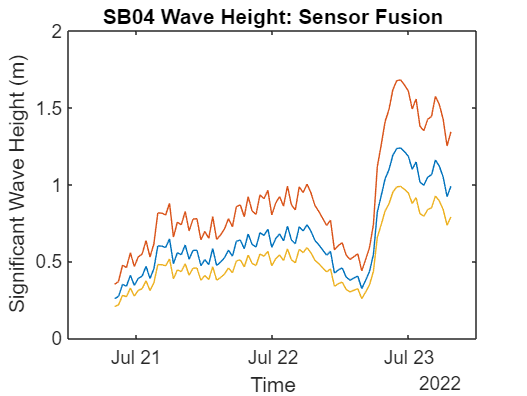

%Exclude time 1> after deployment 
%waveParamTable = waveParamTable(waveParamTable.DateTimeUTC > datetime(2022, 07, 20, 16, 40, 00), :);
%Exclude Time Just before deployment
%waveParamTable = waveParamTable(waveParamTable.DateTimeUTC < datetime(2022, 07, 24, 13, 00, 00), :);

plot(waveParamTable.DateTimeUTC(2:end-2), waveParamTable.Hm0(2:end-2), waveParamTable.DateTimeUTC(2:end-2), waveParamTable.Hm0_upper(2:end-2), waveParamTable.DateTimeUTC(2:end-2), waveParamTable.Hm0_lower(2:end-2));
title("SB04 Wave Height: Sensor Fusion");
xlabel('Time');
ylabel('Significant Wave Height (m)');

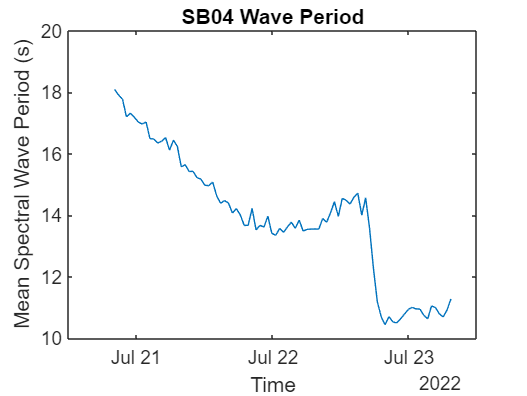


plot(waveParamTable.DateTimeUTC(2:end-2), waveParamTable.Tm01(2:end-2))
title("SB04 Wave Period");
xlabel('Time');
ylabel('Mean Spectral Wave Period (s)');

## Plot Multiple Time Series: Multiple Buoys

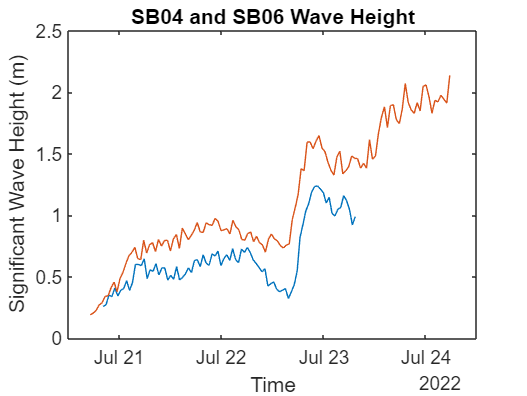

%Exclude time 1> after deployment 
%waveParamTable = waveParamTable(waveParamTable.DateTimeUTC > datetime(2022, 07, 20, 20, 10, 00), :);
%Exclude Time Just before deployment
%waveParamTable = waveParamTable(waveParamTable.DateTimeUTC < datetime(2022, 07, 24, 8, 20, 00), :);


%Store previously processed data from another buoy
%Comment out before using 
% SB04Tm01 = waveParamTable.Tm01(2:end-1);
% SB04Hm0 = waveParamTable.Hm0(2:end-1);
% SB04Hm0Upper = waveParamTable.Hm0_upper(2:end-1)
% Sb04Hm0Lower = waveParamTable.Hm0_lower(2:end-1)
% SB04Datetime = waveParamTable.DateTimeUTC(2:end-1);

plot(waveParamTable.DateTimeUTC(2:end-2), waveParamTable.Hm0(2:end-2), SB04Datetime(2:end-2), SB04Hm0(2:end-2));
title("SB04 and SB06 Wave Height");
xlabel('Time');
ylabel('Significant Wave Height (m)');

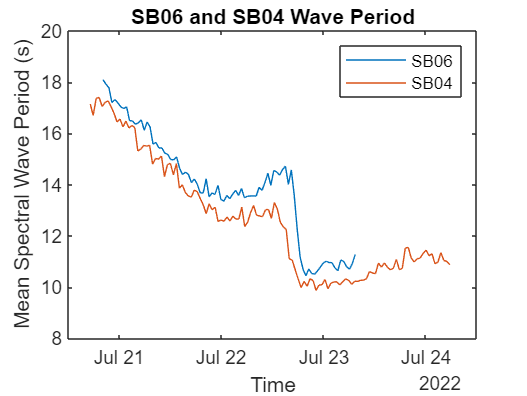



plot(waveParamTable.DateTimeUTC(2:end-2), waveParamTable.Tm01(2:end-2), SB04Datetime(2:end-2), SB04Tm01(2:end-2))
title("SB06 and SB04 Wave Period");
xlabel('Time');
ylabel('Mean Spectral Wave Period (s)');
legend("SB06", "SB04");

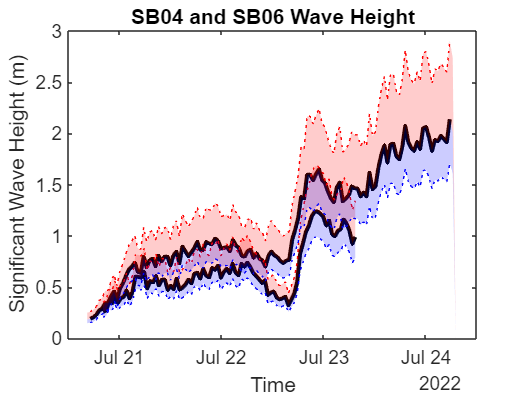


plot(waveParamTable.DateTimeUTC(2:end-2), waveParamTable.Hm0(2:end-2), "LineWidth", 2, "Color", "black");
title("SB04 and SB06 Wave Height");
xlabel('Time');
ylabel('Significant Wave Height (m)');
hold on 
plot(SB04Datetime(2:end-2), SB04Hm0(2:end-2), "LineWidth", 2, "Color", "black")
hold on 
plot(waveParamTable.DateTimeUTC(2:end-2), waveParamTable.Hm0_lower(2:end-2), "LineWidth", 0.5, "LineStyle", ":", "Color", "blue"); 
hold on
plot(waveParamTable.DateTimeUTC(2:end-2), waveParamTable.Hm0_upper(2:end-2), "LineWidth", 0.5, "LineStyle", ":", "Color", "red"); 
hold on 
patch([waveParamTable.DateTimeUTC(2:end-2); flipud(waveParamTable.DateTimeUTC(2:end-2))], [waveParamTable.Hm0_upper(2:end-2); flipud(waveParamTable.Hm0(2:end-2))]', 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle', 'none');
hold on
patch([waveParamTable.DateTimeUTC(2:end-2); flipud(waveParamTable.DateTimeUTC(2:end-2))], [waveParamTable.Hm0(2:end-2); flipud(waveParamTable.Hm0_lower(2:end-2))]', 'b', 'FaceAlpha',0.2, 'EdgeColor', 'none', 'LineStyle', 'none')  
hold on
plot(SB04Datetime(2:end-2), Sb04Hm0Lower(2:end-2), "LineWidth", 0.5, "LineStyle", ":", "Color", "blue"); 
hold on 
plot(SB04Datetime(2:end-2), SB04Hm0Upper(2:end-2), "LineWidth", 0.5, "LineStyle", ":", "Color", "red"); 
hold on 
patch([SB04Datetime; flipud(SB04Datetime)], [SB04Hm0Upper; flipud(SB04Hm0)]', 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle', 'none');
hold on
patch([SB04Datetime; flipud(SB04Datetime)], [SB04Hm0; flipud(Sb04Hm0Lower)]', 'b', 'FaceAlpha',0.2, 'EdgeColor', 'none', 'LineStyle', 'none');
hold off 

## Multiple Plots: Sensor Fusion comparison

%Exclude Time Just before retrieval
waveParamTable = waveParamTable(waveParamTable.DateTimeUTC < datetime(2022, 07, 24, 1, 00, 00), :);
SB04ParamFuse = SB04ParamFuse(SB04ParamFuse.DateTimeUTC < datetime(2022, 07, 24, 1, 00, 00), :);

plot(waveParamTable.DateTimeUTC(2:end-1), waveParamTable.Hm0(2:end-1), SB04ParamFuse.DateTimeUTC, SB04ParamFuse.Hm0);
title("SB04 Sensor Fusion Vs Heave Hm0");
xlabel('Time');
ylabel('Significant Wave Height (m)');
legend("Heave", "Sensor Fusion")

plot(waveParamTable.DateTimeUTC(2:end-1), waveParamTable.Tm01(2:end-1), SB04ParamFuse.DateTimeUTC, SB04ParamFuse.Tm01)
title("SB04 Sensor Fusion Vs Heave Tm01");
xlabel('Time');
ylabel('Mean Spectral Wave Period (s)');
legend("Heave", "Sensor Fusion")

plot(waveParamTable.DateTimeUTC(2:end-1), waveParamTable.Hm0(2:end-1), "LineWidth", 2, "Color", "black");
title("SB04 Sensor Fusion Vs Heave Hm0");
xlabel('Time');
ylabel('Significant Wave Height (m)');
hold on 
plot(SB04ParamFuse.DateTimeUTC, SB04ParamFuse.Hm0, "LineWidth", 2, "Color", 'green')
hold on 
plot(waveParamTable.DateTimeUTC(2:end-1), waveParamTable.Hm0_lower(2:end-1), "LineWidth", 0.5, "LineStyle", ":", "Color", "blue"); 
hold on
plot(waveParamTable.DateTimeUTC(2:end-1), waveParamTable.Hm0_upper(2:end-1), "LineWidth", 0.5, "LineStyle", ":", "Color", "red"); 
hold on 
patch([waveParamTable.DateTimeUTC(2:end-1); flipud(waveParamTable.DateTimeUTC(2:end-1))], [waveParamTable.Hm0_upper(2:end-1); flipud(waveParamTable.Hm0(2:end-1))]', 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle', 'none');
hold on
patch([waveParamTable.DateTimeUTC(2:end-1); flipud(waveParamTable.DateTimeUTC(2:end-1))], [waveParamTable.Hm0(2:end-1); flipud(waveParamTable.Hm0_lower(2:end-1))]', 'b', 'FaceAlpha',0.2, 'EdgeColor', 'none', 'LineStyle', 'none')  
hold on
plot(SB04ParamFuse.DateTimeUTC, SB04ParamFuse.Hm0_lower, "LineWidth", 0.5, "LineStyle", ":", "Color", "blue"); 
hold on 
plot(SB04ParamFuse.DateTimeUTC, SB04ParamFuse.Hm0_upper, "LineWidth", 0.5, "LineStyle", ":", "Color", "red"); 
hold on 
patch([SB04ParamFuse.DateTimeUTC; flipud(SB04ParamFuse.DateTimeUTC)], [SB04ParamFuse.Hm0_upper; flipud(SB04ParamFuse.Hm0)]', 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle', 'none');
hold on
patch([SB04ParamFuse.DateTimeUTC; flipud(SB04ParamFuse.DateTimeUTC)], [SB04ParamFuse.Hm0; flipud(SB04ParamFuse.Hm0_lower)]', 'b', 'FaceAlpha',0.2, 'EdgeColor', 'none', 'LineStyle', 'none');
legend("Heave", 'Sensor Fusion', '', '', '', '', '', '', '');
hold off 

## Shaded Confidence Intervals

plot(waveParamTable.DateTimeUTC(2:end-1), waveParamTable.Hm0(2:end-1), "LineWidth", 2, "Color", "black");
title("SB06 Wave Height");
xlabel('Time');
ylabel('Significant Wave Height (m)');
hold on 
plot(waveParamTable.DateTimeUTC(2:end-1), waveParamTable.Hm0_lower(2:end-1), "LineWidth", 0.5, "LineStyle", ":", "Color", "blue"); 
hold on
plot(waveParamTable.DateTimeUTC(2:end-1), waveParamTable.Hm0_upper(2:end-1), "LineWidth", 0.5, "LineStyle", ":", "Color", "red"); 
hold on 
patch([waveParamTable.DateTimeUTC(2:end-1); flipud(waveParamTable.DateTimeUTC(2:end-1))], [waveParamTable.Hm0_upper(2:end-1); flipud(waveParamTable.Hm0(2:end-1))]', 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle', 'none');
hold on
patch([waveParamTable.DateTimeUTC(2:end-1); flipud(waveParamTable.DateTimeUTC(2:end-1))], [waveParamTable.Hm0(2:end-1); flipud(waveParamTable.Hm0_lower(2:end-1))]', 'b', 'FaceAlpha',0.2, 'EdgeColor', 'none', 'LineStyle', 'none')  
hold off
